# Time Vector

close all

% Sampling Frequency
fs = 1e3;       % 1000 Hz

% Sampling time
dT = 1/fs;      % 1 ms

% Total Time
T = 1;          % 1 s

% Time vector
t = dT:dT:T;


## One sinusoid

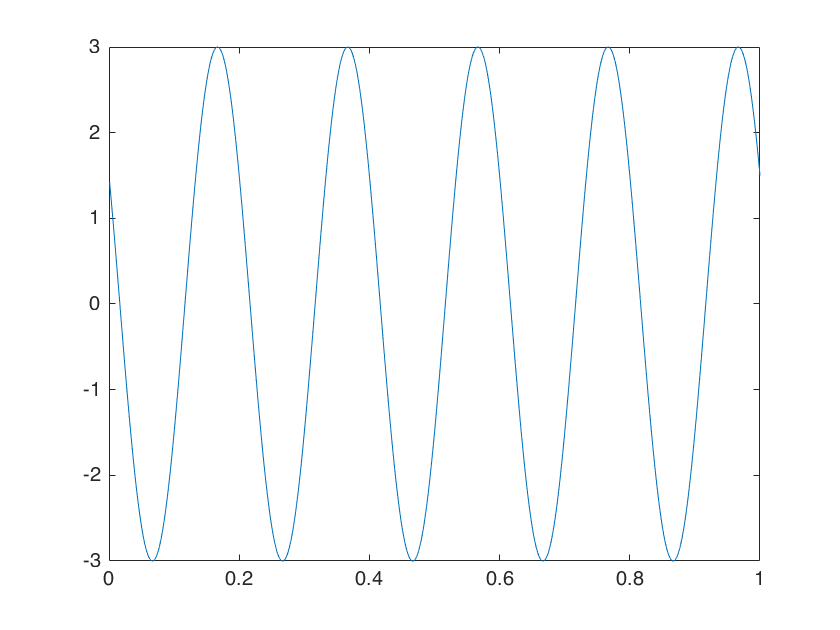

% Amplitude
a = 3;

% Phase
ph=pi/3;

% Frequency
f = 5;          % 5 Hz, a.k.a. 5 peaks per second

% Radial frequency
w = 2*pi*f;

% Signal
x = a*cos(w*t+ph);

plot(t,x)

## Multiple Sinusoids

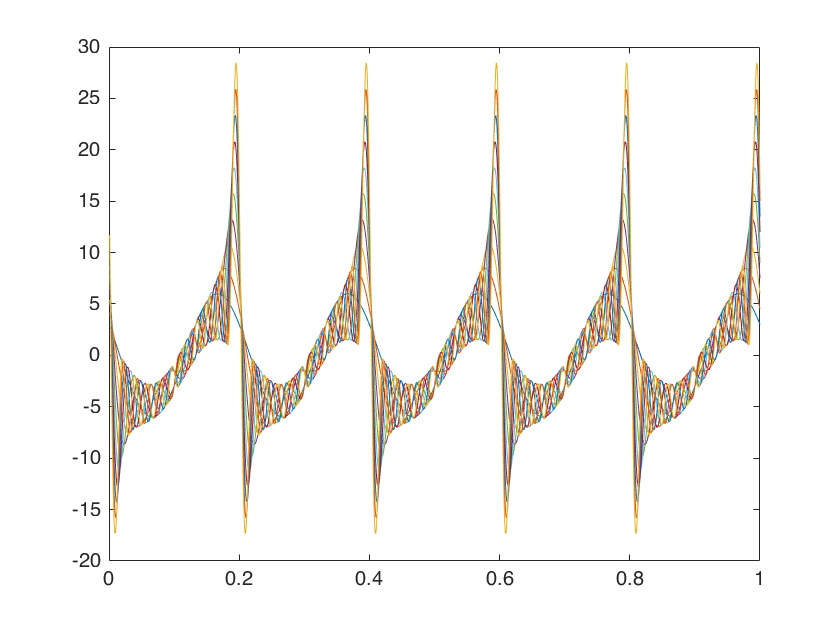

figure
for h = 1:10
    % Frequency
    f = 5*h;        
    
    % Radial frequency
    w = 2*pi*f;
    
    % Signal
    x = x + a*cos(w*t+ph);
    
    plot(t,x)
    hold on
    
    pause(0.5)
    
end

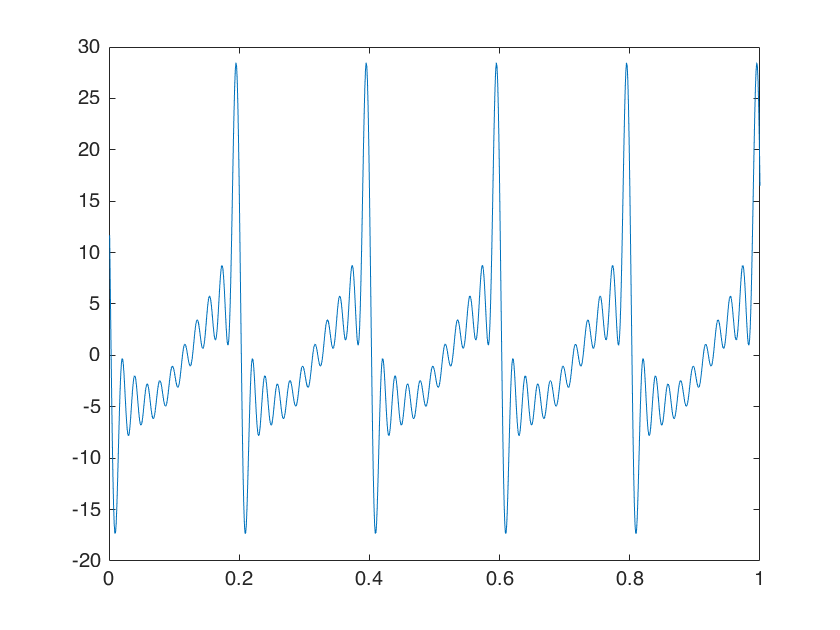


figure
plot(t,x)

## Bonus: Square wave using sinusoids

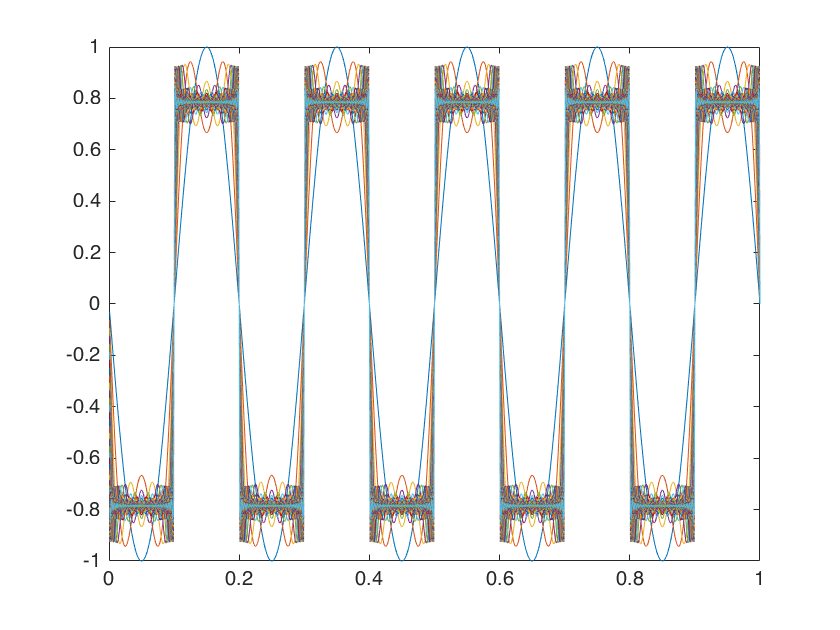

% Reset x to a vector of 0
x = zeros(size(t));

% New Phase
ph = pi/2;

figure
for h = 1:2:21 % Try going up to 151
    % Frequency
    f = 5*h;       
        
    % Radial frequency
    w = 2*pi*f;
    
    % Amplitude (Note: it's frequency-dependent!)
    a = 10*pi/w;
    
    % Signal
    x = x + a*cos(w*t+ph);
    
    plot(t,x)
    hold on
    
    pause(0.5)
    
end

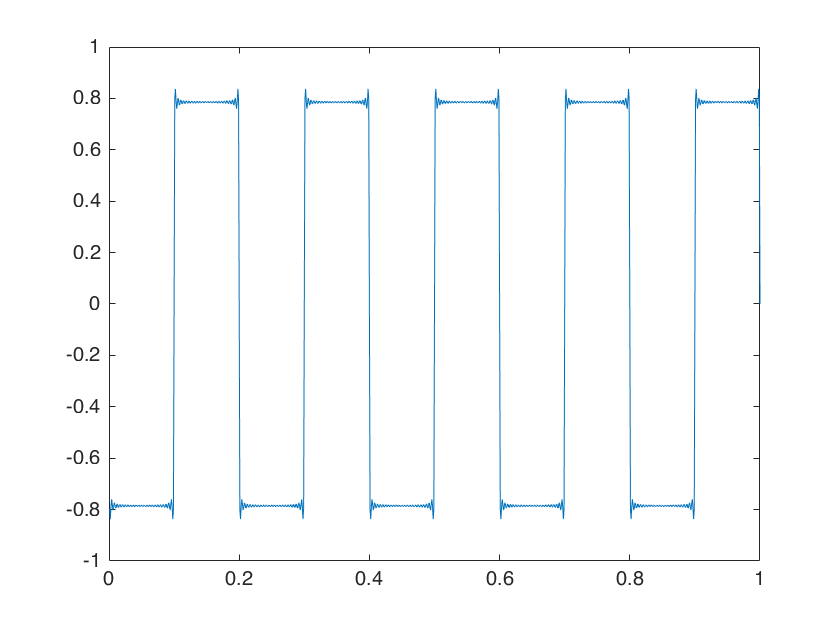


figure
plot(t,x)